% 七个国家
% 加拿大、日本、意大利、美国、英国、中国、印度
% 结构体注释
% Utility本国总福利
% Discount福利贴现率
% Alpha风险厌恶系数
% Population当期人口
% Consume消费
% GDP
% CO2
% Investment投资、
% Export出口
% Import进口
% CO2_bechmark 基准值、当前较基准值比例、目标比例
% Utility = sum((1+Discount)^(-t)*Population*(Consume/Population)^(1-Alpha)/(1-Alpha))
% GDP = Consume + Investment + Export -Import (忽略政府购买)
% 本国CO2如何影响GDP,Investment,Export；外国CO2如何影响Import（发达国家和发展中国家应不一致）
% 约束条件设置
% 初始状态设置
% 以2020为1，从2021开始，假设年初确定未来30年方案
% 贴现率统一为1.5%
% CO2的基准值
%%
%七国历史CO2变化率diff(CO2)/bench
Benchmark = [458.007 1158.007 439.55 5113.455 600.344 5876.555 1185.953];
%.时间权重（越近影响越大）
CO2_changerate(1,:) = Canada_data./Benchmark(1); 
CO2_changerate(2,:) = JAPAN_data(:,1)./Benchmark(2); 
CO2_changerate(3,:) = Italy_data./Benchmark(3); 
CO2_changerate(4,:) = US_data(:,1)./Benchmark(4); 
CO2_changerate(5,:) = UK_data(:,1)./Benchmark(5); 
CO2_changerate(6,:) = CHINA_data(:,1)./Benchmark(6); 
CO2_changerate(7,:) = India_data./Benchmark(7); 
w = 1 : 55;%时间权重
%扩充样本
for j =2 : w(end)
    CO2_changerate = cat(2,CO2_changerate, CO2_changerate(:,j)*ones(1,j-1));
end
ceil_CO2 = zeros(7,2);
for i =1 : 7    
    ceil_CO2(i,:) = prctile(CO2_changerate(i,:),[2.5 97.5]);%考虑样本的时间权重
    %ceil_CO2(i,1) = 2*ceil_CO2(i,1);%减排力度翻倍
    %{
    figure();
    histogram(CO2_changerate(i,:),10);    
    disp(['均值：' num2str(mean(CO2_changerate(i,:)))]);
    disp(['均值+-一倍标准差：' num2str(mean(CO2_changerate(i,:))-std(CO2_changerate(i,:))) ' ' ...
        num2str(mean(CO2_changerate(i,:))+std(CO2_changerate(i,:)))]);
    disp(['均值+-两倍标准差：' num2str(mean(CO2_changerate(i,:))-2*std(CO2_changerate(i,:))) ' ' ...
        num2str(mean(CO2_changerate(i,:))+2*std(CO2_changerate(i,:)))]);
    %}
end
ceil_CO2(6,1) = ceil_CO2(6,1) - 0.06;%中国减排能力提升值
%ceil_CO2(7,:) = ceil_CO2(7,:) -0.1;


format short;
tic;
%设置迭代步数
Interation = 1;%用于找中国减排能力提升值
%每行用于预测一国C
%线性CO2
matrix_cof = [-185.72, 0.2787, 0.1617, 0.6803, -0.1036, 0.1817, -0.0016, 0.2411;
    -16620, 1.60, 30.17, 118.05, -4.78, 14.41, -4.03, 47.21;
    -321700, 32.61, 43.92, 884.31, -37.65, 128.18, -4.22, 229.81;
    -7142.43, 6.56, 2.69, 21.46, -2.07, 2.85, 0.04, 6.54;
    -347500, 28.46, 135.67, 996.39, -71.05, 93.52, 2.61, 242.71;
    -4043000, 1299.7935, 659.2740, -1805.6871, -345.0057, 3788.4433, 53.8290, 4787.2267;
    -10570000, -17999, 5876.80, 10990, -25.03, 6033.31, -925.55, 13090];
%对数CO2
matrix_cof_l = [-222.0884 502.8295 485.7459 468.5894 -1611.9483 218.0350 51.7596 532.5825;
    -324200 87890 70990 74490 -102100 -1328.8428 -20900 72310;
    -1863000 320700 71510 620000 -657400 123500 54360 427200;
    -30210 10410 8939.9955 16200 -33780 3882.3171 2050.3704 15370;
    -1527000 202500 372800 736000 -1113000 102200 111800 520400;
    -20650000 -3427000 6230000 -2552000 -11100000 5943000 105600 14830000;
    -49570000 -14250000 19400000 5730000 -13580000 3920000 -7313000 28240000];
Population_total = xlsread('人口预测.xls');  % load data
T = 30;
K = 1000000000;
Canada = struct('Utility', 0, 'Discount', 0.015, 'Alpha', 0.12, 'Population', K*Population_total(1:T + 1, 8), ...
    'Consume', 1000, 'GDP', 1000, 'CO2', zeros(1,30), 'Investment', 200, 'Export', 300,'Import',200,'CO2_bechmark',[458.007,535.823/458.007,0.2]);
Japan = struct('Utility', 0, 'Discount', 0.015, 'Alpha', 0.31, 'Population', K*Population_total(1:T + 1, 7), ...
    'Consume', 1000, 'GDP', 1000, 'CO2', zeros(1,30), 'Investment', 200, 'Export', 300,'Import',200,'CO2_bechmark',[1158.007,1030.775/1158.007,0.2]);
Italy = struct('Utility', 0, 'Discount', 0.015, 'Alpha', 0.35, 'Population', K*Population_total(1:T + 1, 6), ...
    'Consume', 1000, 'GDP', 1000, 'CO2', zeros(1,30), 'Investment', 200, 'Export', 300,'Import',200,'CO2_bechmark',[439.55,303.815/439.55,0.2]);
US = struct('Utility', 0, 'Discount', 0.015, 'Alpha', 0.24, 'Population', K*Population_total(1:T + 1, 3), ...
    'Consume', 1000, 'GDP', 1000, 'CO2', zeros(1,30), 'Investment', 200, 'Export', 300,'Import',200,'CO2_bechmark',[5113.455,4712.771/5113.455,0.2]);
UK = struct('Utility', 0, 'Discount', 0.015, 'Alpha', 0.23, 'Population', K*Population_total(1:T + 1, 5), ...
    'Consume', 1000, 'GDP', 1000, 'CO2', zeros(1,30), 'Investment', 200, 'Export', 300,'Import',200,'CO2_bechmark',[600.344,329.579/600.344,0.2]);
China = struct('Utility', 0, 'Discount', 0.015, 'Alpha', 0.62, 'Population', K*Population_total(1:T + 1, 4), ...
    'Consume', 1000, 'GDP', 1000, 'CO2', zeros(1,30), 'Investment', 200, 'Export', 300,'Import',200,'CO2_bechmark',[5876.555,10667.887/5876.555,0.5]);
India = struct('Utility', 0, 'Discount', 0.015, 'Alpha', 0.43, 'Population', K*Population_total(1:T + 1, 2), ...
    'Consume', 1000, 'GDP', 1000, 'CO2', zeros(1,30), 'Investment', 200, 'Export', 300,'Import',200,'CO2_bechmark',[1185.953,2441.792/1185.953,0.8]);
Country_7 = [Canada, Japan, Italy, US, UK, China, India];
U_total = zeros(201,7);

%记录各年年初CO2政策1以及年末累积减排2以及累积福利 7*30*3 
Record_CO2 = zeros(7, 30, 3);
s = 0;
while s < 7
for i = 1 : Interation
    disp(['Interation' num2str(i)])
    %初始化
    s = 0;
    for j = 1:7
        Country_7(j).Utility = 0;
        Country_7(j).CO2 = zeros(1,30);
    end
    %求每一步的最优解
    %ceil_CO2(6,1) = ceil_CO2(6,1) - 0.035;%中国减排能力提升值设置- 0.001*i - 0.005*Interation
    [Country_7, U_total] = D4_1(Country_7, matrix_cof_l, T, ceil_CO2);
    for n = 1:7
        Record_CO2_2(n,:,1) = Country_7(n).CO2;
        for j = 1:T
            Record_CO2_2(n,j,2) = sum(Country_7(n).CO2(1:j)) + Country_7(n).CO2_bechmark(2);
        end
        s = s + (Record_CO2_2(n,end,2) <=Country_7(n).CO2_bechmark(3));
        % 检验中国是否碳中和
    end
    s    
        
    %初始化下一步的数据
    %假设一次迭代2021~2050，此部分暂时无用
    %{
    %人口
    Country_7(1).Populaiton = K*Population_total(i + 1:T + i + 1, 8);
    Country_7(2).Populaiton = K*Population_total(i + 1:T + i + 1, 7);
    Country_7(3).Populaiton = K*Population_total(i + 1:T + i + 1, 6);
    Country_7(4).Populaiton = K*Population_total(i + 1:T + i + 1, 3);
    Country_7(5).Populaiton = K*Population_total(i + 1:T + i + 1, 5);
    Country_7(6).Populaiton = K*Population_total(i + 1:T + i + 1, 4);
    Country_7(7).Populaiton = K*Population_total(i + 1:T + i + 1, 2);    
    %CO2&记录    
    for j = 1 : 7
        %累积值取当前和0中最大的，排除负值
        con = Country_7(j).CO2_bechmark(2);
        Country_7(j).CO2_bechmark(2) = max([Country_7(j).CO2_bechmark(2) + Country_7(j).CO2(1) 0]);
        %调整记录的CO2政策
        Record_CO2(j, i, 1) = Country_7(j).CO2_bechmark(2) - con;
        Record_CO2(j, i, 2) = Country_7(j).CO2_bechmark(2);
        Record_CO2(j, i, 3) = Country_7(j).Utility;
        Record_CO2(j, i, 3) = sum(Record_CO2(j, 1 : i, 3));
    end
    %CO2政策
    Country_7(1).CO2 = [Country_7(1).CO2(2:30) 0];
    Country_7(2).CO2 = [Country_7(2).CO2(2:30) 0];
    Country_7(3).CO2 = [Country_7(3).CO2(2:30) 0];
    Country_7(4).CO2 = [Country_7(4).CO2(2:30) 0];
    Country_7(5).CO2 = [Country_7(5).CO2(2:30) 0];
    Country_7(6).CO2 = [Country_7(6).CO2(2:30) 0];
    Country_7(7).CO2 = [Country_7(7).CO2(2:30) 0];
    %}
    
end
end

Interation1


nashInteration:1 1 0
nashInteration:2 0 0


s = 7

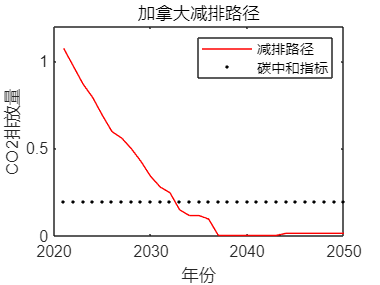

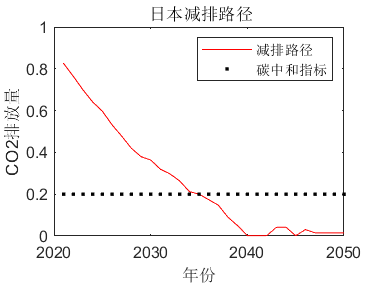

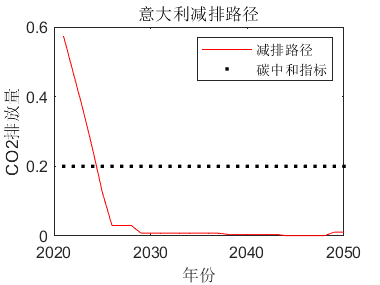

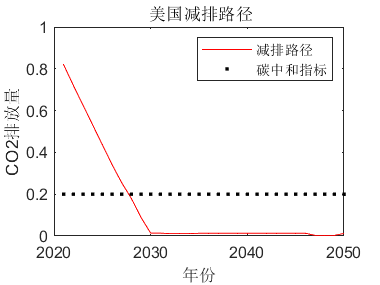

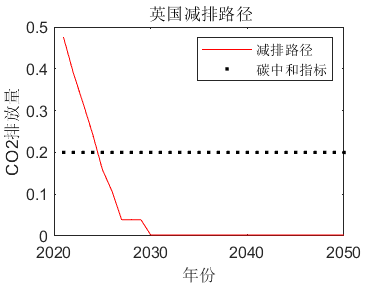

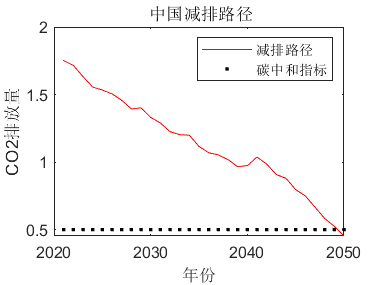

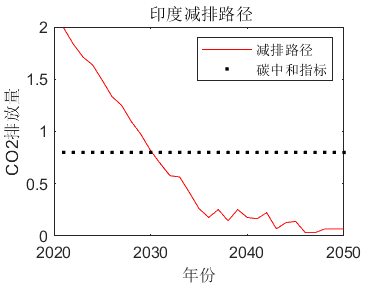


%绘图
clear tag_c;
tag_c = ['加拿大'; ' 日本'; '意大利'; ' 美国'; ' 英国'; ' 中国'; ' 印度'];
for i = 1 : 7
    figure();
    plot(2021:2050,Record_CO2_2(i,:,2),'r-');
    hold on
    plot(2021:2050,Country_7(i).CO2_bechmark(3),'k.');
    xlabel('年份');
    ylabel('CO2排放量');
    title([tag_c(i,:) '减排路径']);
    legend('减排路径','碳中和指标');
end